# Data preprocessing: Wine Dataset

### Author: Jeffrey Pallarés Núñez

## Abstract

En este notebook se realizará un análisis de la base de datos *Wine*,  centrándonos en el preprocesado de la misma, con la intención de obtener un modelo de clasificación óptimo haciendo uso del método de clasificación no supervisado *Kmeans*.

## Introducción

Para realizar este análisis, primero ahondaremos en la información existente del *dataset*, donde, a veces, podemos encontrar información últil previamente a realizar cualquier análisis, luego se estudiarán las features a nivel estádistico y las caracterísitcas intrínsecas del dataset (equilibrado, valores nulos.. etc) y se le aplicará el tratamiendo necesario. Una vez aplicado se le aplicará el modelo de clasificación *kmeans*.

## Metodología

Para obtener las herramientas necesarias como para evaluar y realizar nuestros experimentos, utilizaremos el software comercial *MATLAB*. Un software muy potente y de alto nivel que nos permite generar muestras, desarrollar algoritmos para procesarlas, analizarlas y visualizarlas de una manera sencilla y orgánica.Todas estas pruebas y desarrollos se llevarán a cabo bajo un computador con un sistema operativo de 64 bits; Windows 10, con un procesador Intel Core i7-8550U y 16 GB de memoria RAM.

## Importando nuestros datos

Para obtener nuestros datos, haremos uso del *dataset* *Wine* que ya trae incorporado el mismo software. 

[X,y] = wine_dataset;
X = X'

X = 	1.0e+03 *

    0.0142    0.0017    0.0024    0.0156    0.1270    0.0028    0.0031    0.0003    0.0023    0.0056    0.0010    0.0039    1.0650
    0.0132    0.0018    0.0021    0.0112    0.1000    0.0027    0.0028    0.0003    0.0013    0.0044    0.0011    0.0034    1.0500
    0.0132    0.0024    0.0027    0.0186    0.1010    0.0028    0.0032    0.0003    0.0028    0.0057    0.0010    0.0032    1.1850
    0.0144    0.0019    0.0025    0.0168    0.1130    0.0039    0.0035    0.0002    0.0022    0.0078    0.0009    0.0035    1.4800
    0.0132    0.0026    0.0029    0.0210    0.1180    0.0028    0.0027    0.0004    0.0018    0.0043    0.0010    0.0029    0.7350
    0.0142    0.0018    0.0025    0.0152    0.1120    0.0033    0.0034    0.0003    0.0020    0.0067    0.0011    0.0029    1.4500
    0.0144    0.0019    0.0025    0.0146    0.0960    0.0025    0.0025    0.0003    0.0020    0.0053    0.0010    0.0036    1.2900
    0.0141    0.0022    0.0026    0.0176    0.1210    0.0026    0.0

y= y'

y =      1     0     0
     1     0     0
     1     0     0
     1     0     0
     1     0     0
     1     0     0
     1     0     0
     1     0     0
     1     0     0
     1     0     0


## Características de Wine

### Información previa

Este dataset contiene 178 *examples*, con valores reales positivos, 13 *features* y está etiquetada con 3 clases. A parte también nos proporcionan el número de *examples* por clase [59,71,48].

### Tratamiento de valores nulos

Se trata de un *dataset*, académico donde no hay valores nulos, lo que nos permitirá no tener hacer un estudio para lidiar con ellos teniendo que eliminar datos, *features* o teniendo que sustituirlos por los valores más óptimos.

Para comprobarlo nosotros mismos, podemos obtener los valores nulos por características de manera lógica, sumarlos y encontrar aquellos índices donde hay valores nulos. A parte, de esta forma también podríamos sabercuántos valores nulos hay por característica y en que características de manera fácil.

nan_mat = isnan(X)

nan_mat = 178×13 logical array
   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0


nan_sum = sum(nan_mat)

nan_sum =      0     0     0     0     0     0     0     0     0     0     0     0     0


nan_values = find(nan_sum ~= 0)


nan_values =

  1×0 empty double row vector



### Equilibrado del dataset

El dataset en primer instancia, podríamos decir que está equilibrado, ya que tiene un conjunto de *examples* por clase similar. Aún así no sabemos como estas pequeñas diferencias pueden afectar realmente a la hora de realizar la clasificiación, ya que puede que estas diferencias pueden que afecten de manera notoria al resultado final.

Para comprobarlo, solo tenemos que sumar el conjunto de valores que hay por cada clase:

sum(y)

ans =     59    71    48


### Formateado del dataset

En este caso también sabemos previamente que todos nuestros datos son datos reales, no existen categóricos ni booleanos. Esto lo hemos podido comprobar al realizar la suma. Si hubiera habido algun tipo diferente nos hubiera dado algún tipo de error por hacer el intento de operar con tipos de datos diferentes

### Escalado del dataset

La normalización es necesaria cuando los diferentes valores entre las características de nuestro dataset no están en los mismos rangos, esto puede afectar sobre todo a algoritmos no analíticos, ya que al tener características valores más grandes que otros, nuestro sistema/modelo le estaría dando más importancia a esas caracterísicas con mayores valores.

Para ello haremos un pequeño estudio estadístico, observando como se distribuyen los valores de las caracteristicas, sus valores mínimo u máximos y compararlos entre ellas. Hay una herramienta que nos combina todas información en un solo gráfico que es el que usaremos a continuación el *box and wishkers chart*

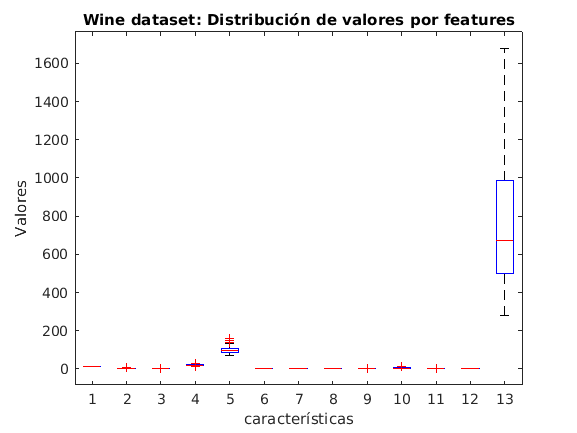

boxplot(X)
title("Wine dataset: Distribución de valores por features")
xlabel('características') 
ylabel('Valores') 

Como podemos observar, hay una homogeneidad devalores que rompen claramente las características 5 y 13. Por lo tanto podremos necesitar nuestros datos. Debido a que es un problema de clasificación haciendo uso de *Kmeans*, y no uno de ajuste de parametros no analítico, pero para eliminar el riesgo realizaremos una escalado escalado de características utilizando la desviación típica, y normalizando en cuanto a la media dándonos como resultado caracterísitcas centradas en la media (0) y con un rango de valores con la similitud necesaria sin modificar su comportamiento/naturaleza para poder ser tratadas por nuestro sistema de manera equánime.

m = mean(X)

m =    13.0006    2.3363    2.3665   19.4949   99.7416    2.2951    2.0293    0.3619    1.5909    5.0581    0.9574    2.6117  746.8933


s = std(X)

s =     0.8118    1.1171    0.2743    3.3396   14.2825    0.6259    0.9989    0.1245    0.5724    2.3183    0.2286    0.7100  314.9075


normalized_X = (X - m)./s

normalized_X =     1.5143   -0.5607    0.2314   -1.1663    1.9085    0.8067    1.0319   -0.6577    1.2214    0.2510    0.3612    1.8427    1.0102
    0.2456   -0.4980   -0.8257   -2.4838    0.0181    0.5670    0.7316   -0.8184   -0.5432   -0.2925    0.4049    1.1103    0.9625
    0.1963    0.0212    1.1062   -0.2680    0.0881    0.8067    1.2121   -0.4970    2.1300    0.2683    0.3174    0.7864    1.3912
    1.6868   -0.3458    0.4866   -0.8070    0.9283    2.4844    1.4624   -0.9791    1.0293    1.1827   -0.4263    1.1807    2.3280
    0.2949    0.2271    1.8352    0.4507    1.2784    0.8067    0.6615    0.2262    0.4003   -0.3184    0.3612    0.4483   -0.0378
    1.4774   -0.5159    0.3043   -1.2861    0.8583    1.5577    1.3623   -0.1756    0.6623    0.7298    0.4049    0.3357    2.2327
    1.7114   -0.4174    0.3043   -1.4657   -0.2620    0.3274    0.4913   -0.4970    0.6798    0.0828    0.2737    1.3638    1.7247
    1.3049   -0.1668    0.8875   -0.5674    1.4884    0.4872    0.48

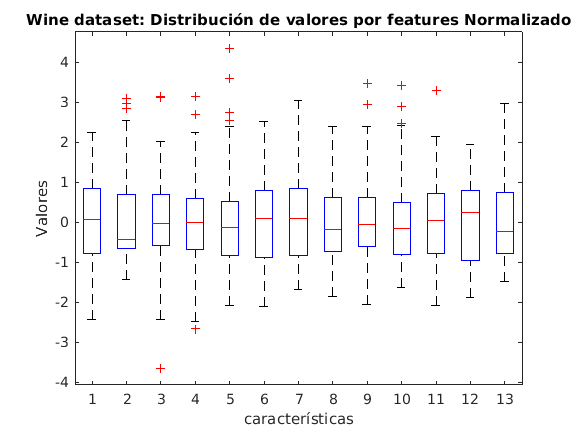

boxplot(normalized_X)
title("Wine dataset: Distribución de valores por features Normalizado")
xlabel('características') 
ylabel('Valores')
hold off;

### Tratamiendo valores outliers

Por último trataremos los outliers, estos valores extremos pueden penalizar en exceso nuestro sistema y más al utilizar métodos basados en la media como el *kmeans*, es más que conocido como es de sensible la media a valores extremos. Por lo tanto identificaremos las características que tienen estos tipos de valores y trataremos de eliminarlos.

Para ello aplicaremos un filtro utilizando las características de la distribución normal, para ello recortaremos las colas asegurándonos un 95,44% de la distribución aproximadamente. Como podemos observar, hemos eliminado la mayoria de outliers y lo que se pueden encontrar se encuentran muy cercanos a los extremos de los intervalos comom ocurria ántes. Igualmente hemos de tener en cuenta que llevando obtenemos una pérdida de información que en algunos caso puede ser útil y que podría impactar en la eficacia de nuestro clasificador.

feats_outliers = [2, 3, 4, 5, 9, 10 ,11]

feats_outliers =      2     3     4     5     9    10    11


grade = 2;

m_outliers = normalized_X(:,feats_outliers);
limit(1,:) = mean(m_outliers) + std(m_outliers) * grade;
limit(2,:) = mean(m_outliers) - std(m_outliers) * grade;

new_x = normalized_X;

for i=1:length(feats_outliers)
    outliers = [find(normalized_X(:,feats_outliers(i)) > limit(1,i)); ...
        find(normalized_X(:,feats_outliers(i)) < limit(2,i))];
    new_x(outliers, feats_outliers(i)) = 0;
    
end
% 
% new_X = rmoutliers(normalized_X)
boxplot(new_x)
title("Wine dataset: Distribución de valores por features Normalizado")
xlabel('características') 
ylabel('Valores')
hold off;


## Reducción de la dimensionalidad

Una de las formas más comunes de conocer la complejidad de nuestra base de datos, es graficándola. Si podemos graficarla podemos observar como se distribuyen los datos, y siendo nuestro problema de clasificiación, si nuestra clases son fácilmente separables. El problema es que  la mayoría de los datasets reales no son graficables, ya que están compuestos de más de 2 dimensiones.

Una de las técnicas más usadas es la reducción de la dimensionalidad. Estas técnicas nos permiten reducir la dimensionalidad con la menor pédida de información posible y teniendo en cuenta la varianza de los datos. Hay que tener en cuenta de que una reducción de la dimensionalidad siempre nos eliminará información que puede ser útil, quedándo entonces la decisión de el número de dimensiones reducidas óptimas de un estudio de los datos.

Estas técnicas también son utilizadas para conseguir un aumento en el rendimiento de los algoritmos que procesen los datos, ya que la disminuir la dimensionalidad, también estaremos reduciendo significativamente el tamaño de los datos a procesar.

Conforme a los resultados, comunmente, suele dar resultados equiparables la clasificación entre datos sin y con una reducción de dimensionalidad, incluso puede que se resientan un poco debido a esa pérdida de información, aunque a veces ocurre lo contrario. Igualmente hay que tener en cuenta de que este proceso no es un proceso que tenga que realizarse con objetivo de mejorar el resultado final en cuanto a error de clasificación *per se*.

Dos de los métodos más usados son *PCA*, y *LDA*.

### Principal Component Analysis (PCA)

Este método es uno de los más usados y conocidos, y se utiliza mucho en el ámbito de compresión de datos. También se puede encontrar en la majoría de ejemplos de problemas en los que se realiza reducción de la dimensionalidad. El problema de este método es que, aunque te conserve la máxima varianza de los datos, te trata los datos como un solo conjunto, por lo tanto a la hora de "girar los ejes* y proyectar sobre ellos, no tendrá en cuenta la importancia inherente que existe entre la diferentes clases, lo que hace que su uso no sea recomendado aplicarlo a datos donde nuestro problema sea realizar una clasificación. En este caso la aplicación del mismo no supone un problema grave al estar nuestros agrupados y bien separados no se generan superposiciones.

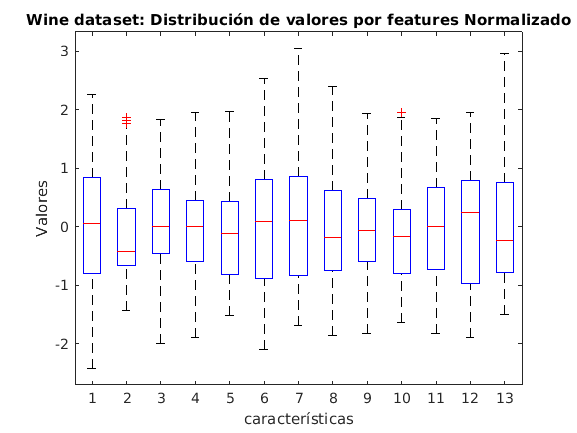

new_y = zeros(length(y),1);

for i=1:size(y, 2)
    index = find(y(:, i)~=0);
    new_y(index, 1) = i;
end
new_y;

hold off;

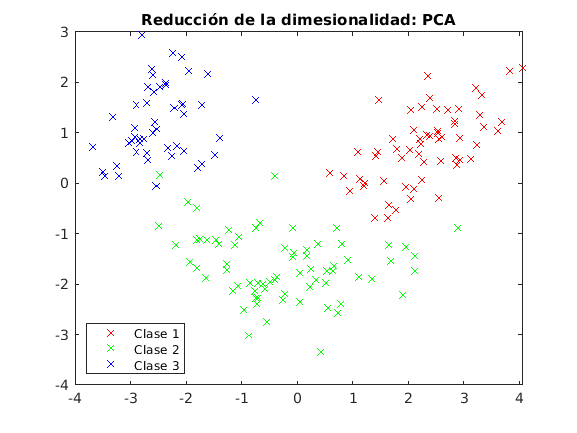


[W, ~] = pca(new_x');

x_reduced = W * new_x';
x_reduced = x_reduced';

colors = 'rgb';

for i=1:max(new_y)
    ind = find(new_y==i);
    plot(x_reduced(ind,1), x_reduced(ind,2), strcat('x',colors(i))),hold on;
end
hold off;
title("Reducción de la dimesionalidad: PCA")
legend("Clase 1", "Clase 2", "Clase 3", "Location", "southwest")

### Linear Discriminant Analysis (LDA)

Cuando nuestro problema sea de clasificación, este será nuestro método a usar. *LDA* o *método de fisher*, es un método que se puede usar para la reducción de la dimensionalidad y a diferencia de *PCA*, sí tiene en cuenta las clases e intenta maximizar la separación entre ellas. Como podemos observar en las distintas gráficas, aunque debido a la naturaleza de nuestros datos, tampoco existen enormes diferencias, si podemos observar como la disposición de los datos haciendo uso de *LDA*, es mucho más óptima para la resolución de nuestro problema.

W = fisher(new_x', new_y', 2)

W =     0.0637   -0.0444   -0.0386   -0.1624    0.0272   -0.1982    0.7099    0.0653    0.0430   -0.3907    0.2132    0.3345    0.3257
    0.5220    0.1036    0.1949   -0.0801    0.2004   -0.0264   -0.1296   -0.0289   -0.2129    0.2724   -0.3220    0.0962    0.6176


eigenv =     9.5757
    1.1124


W =     0.0637   -0.0444   -0.0386   -0.1624    0.0272   -0.1982    0.7099    0.0653    0.0430   -0.3907    0.2132    0.3345    0.3257
    0.5220    0.1036    0.1949   -0.0801    0.2004   -0.0264   -0.1296   -0.0289   -0.2129    0.2724   -0.3220    0.0962    0.6176


x_reduced = W * new_x';
x_reduced = x_reduced';

colors = 'rgb';

for i=1:max(new_y)
    ind = find(new_y==i);
    plot(x_reduced(ind,1), x_reduced(ind,2), strcat('x',colors(i))),hold on;
end
hold off;
title("Reducción de la dimesionalidad: LDA")
legend("Clase 1", "Clase 2", "Clase 3", "Location", "southwest")


## Clasificador haciendo uso del algorítmo Kmeans.

Kmeans es un algoritmo de clustering *no supervisado*, pero en nuestro caso, utilizaremos sus características entrenar nuestro modelo y  luego realizar un clasificador de mínima distancia, al conocer la clases y el número de clases, que es 3, haremos uso del algorítmo sabiendo previamente el *K* óptimo. Este proceso hay que realizarlo con sumo cuidado, ya que podemos representar nuestros datos, podremos ver si los centroides se distribuyen de forma óptima o razonable, porque realmente, aunque sepamos el número de clases/clusters real, el algoritmo *Kmeans* no te asegura que se distribuyan entre las 3 clases de nuestros datos, es decir depende de la distribución de nuestros datos, puede que dos centroides se distribuyan en una misma clase, detectando subclases y esto es algo a tener muy en cuenta y que puede impactar notablemente en el resultado final.

### Validación HOLD OUT

Debido que nuestro objetivo no es tanto realizar una total correcta clasificación y que contamos con un dataset académico nos conformaremos con una validación *HOLD OUT*. Para ellos realizaremos una partición de datos de un 70% para entrenar nuestro modelo y un 30% para validarlo.

ind = randperm(size(new_y, 1));
indtrain = ind(1:(length(ind) * 0.7));

indtest = ind(length(indtrain)+1:end);

xtrain = x_reduced(indtrain,:);
ytrain = x_reduced(indtrain,:);

xtest = x_reduced(indtest,:);
ytest = x_reduced(indtest,:);


### Kmeans: Entreamiento de nuestro modelo

Para realizar el entrenamiento utilizando *Kmeans*, en vez de generar los centroides de manera aleatoria, utilzaremos como centroides iniciales el valor medio de los patrones por cada clase, asegurándonos que éstos queden distribuidos adecuadamente entre las 3 clases.

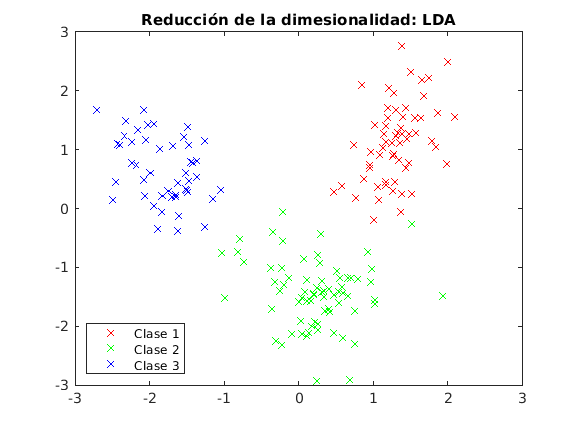

m = zeros(2,3);
n_classes = max(new_y);
for i=1:n_classes
    ind = find(new_y(indtrain)==i);
    mean_pat = meanpat(xtrain(ind,:)');
    m(:,i) = mean_pat;
    C{i} = covpat(xtrain(ind,:)');

end

cc = mykmeans(xtrain',n_classes,m);

### Evaluación del modelo

Para evaluarlo usaremos dos distancias, la distancia euclidea y la distancia de mahalanobis. La distancia de mahalanobis suele trabajar mejor con este tipo de muestra ya que tiene en cuenta la tendencia y la varianza ya que hace uso de la covarianza. Este caso, al estar nuestra clases tan bien diferenciadas, los resultados son prácticamente idénticos.

### Función de error

Como función de error, utilizaremos número de *ejemplos* mal clasificados. Con ello calcularemos la tasa de *ejemplos* bien clasificados.

%% Clasificación distancia mínima: Distancia Euclidea
for i=1:n_classes
    d(i,:) = d_euclid(xtest',cc(:,i));
end

[~,yest]=min(d);
t_acierto_total_de = 100*sum((new_y(indtest))' ==yest)/length(yest);

%% Clasificacion distancia mínima: Distancia de mahalanobis.
for i=1:n_classes
    d(i,:)=d_mahal(xtest',cc(:,i),C{i});
end
[~,yest]=min(d);
t_acierto_total_dm = 100*sum((new_y(indtest))' ==yest)/length(yest);


## Resultados

Como podemos ver, la clasificación se ha realizado de manera satisfactoria debido a que los centroides se han distribuido de manera uniforme entre las 3 clases. Esto ha sido debido tanto la limpieza previa de nuestros datos, como posicionar de manera inicial los centroides en la media de cada una de las clases, haciendo que convergan hacia la posición óptima que nos ha permitido clasificar de una manera excepcional, con una tasa de acierto superior al 98%.

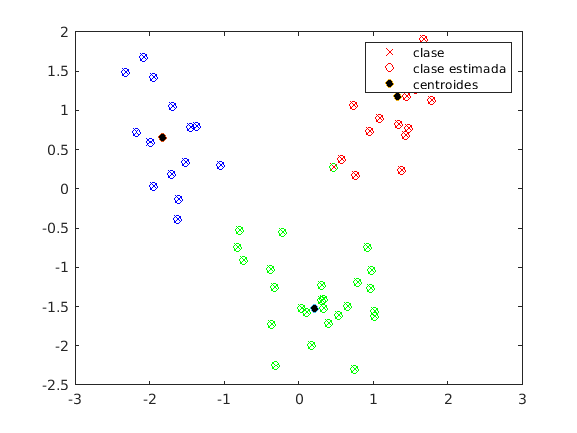

colors = 'rgb';

for i=1:max(new_y)
    ind = find(new_y(indtest)==i);
    indest = find(yest == i);
    plot(xtest(ind,1), xtest(ind,2), strcat('x',colors(i))),hold on;
    plot(xtest(indest,1), xtest(indest,2), strcat('o',colors(i)))
    plot(cc(1,i), cc(2,i), 'o', 'MarkerFaceColor','k')
end

c = legend('clase ', 'clase estimada', 'centroides');

hold off;